# **Tokens positions in Monopoly as a Markov process**

## **Introduction**

Here's a little project I worked on while studying for the Probability exam, during the second year of my Bachelor of Science in Mathematical Engineering at Politecnico di Milano in May 2023. 

The last section of the course was about descrete-time Markov chains, which I particularly enjoyed. During a lesson, I realised that, with some approximations (not that subtle, to be honest...), it is possible to describe the random evolution of a player's token position using this mathematical model. Since I was learning to program with MATLAB in that same period, I decided to use this programming language to build it.

Since there are now many different versions of the game, I decided to refer to the standard British version.

If you find any mistakes or typos, please tell me: your remarks or corrections are very welcome.

## What is a descrete time Markov chain?

Before we begin, I’d like to briefly remind you that a discrete-time Markov chain is a stochastic process (i.e., a sequence of random variables) that satisfies the Markov property: the value of the next variable depends only on the value of the current variable. The random transition from one state to another is described at each time step by the so-called “Transition Matrix.” This matrix, usually denoted by *P*, is a square matrix with dimensions equal to the number of possible states. Each element of *P* is such that the entry in row *i* and column *j* represents the probability of moving to the *j*-th state from the *i*-th state.

In our case, the possible states correspond to the spaces on the Monopoly board.

## Approximations

Here are the approximations I had to make:

- **Chance and Community Chest**: in order to adhere to the definition of Markov chains in my model, I assumed that every time a player draws a Chance or Community Chest card, it must be placed back into the deck (even the "*Get Out of Jail Free*" card), and the deck reshuffled. This ensures that every card in both decks has the same probability of being drawn each time a player lands on one of those spaces.

- *Jail*: Here come a few more problems. There are many discussions about what the legitimate ways are to get out of *Jail* in Monopoly. I hope the reader can forgive me, but I'll go my way. You can escape *Jail* by paying a fine before rolling the dice, by using the "*Get Out of Jail Free*" card (if you have one), or by throwing doubles on any of the first three turns (if this doesn't happen, you have to pay the fine before the fourth turn). As you can imagine, the approximations I had to make in order to build the Markov chain model are quite significant here too. First of all, I assumed that at every turn, the player in *Jail* decides with equal probability to pay the fine or to try their luck and roll the dice. Unfortunately, I couldn't consider the possible possession of a "*Get Out of Jail Free*" card, and neither could I count the number of turns a player stays in *Jail*. This is because, I repeat, discrete-time Markov Chains describe the discrete-time evolution of events that depend only on their previous state.

The reader will observe the effect of these approximations later in this document (once again, if you find these approximations wrong or improvable, please let me know).

**Here ends the tedious bureaucratic part and the fun begins!**

## **Building P**

First of all, let's build the *P* transition matrix, where the *P(i, j)* element describes the probability of moving to the *j*-th space on the next turn starting from the *i*-th. Note that the actual number of spaces is 41 instead of 40, with *Jail* and *Just Visiting* considered as separate spaces. Since vectors and matrix indices in MATLAB start from 1, I decided to enumerate the board's spaces from 1 (GO!) to 41: in this case, space number 10 corresponds to *Just Visiting,* and number 41 to *Jail* (I assigned it the last number because you can not go to *Jail* by landing on the tenth space). On each row of *P* (which represents the space you're currently on), you can read the probabilities of landing in each of the board's spaces in the next dice roll under their respective column.

Let's create a vector representing the probabilities of obtaining numbers from 2 to 12 with a dice roll:

dice_roll_prob = 1/36*[1:6, 5:-1:1];

Now we begin the construction of the *P* matrix:

% first filling: the initial matrix is a 40x40 square matrix. We'll add the
% last row and column later...
l = length(dice_roll_prob);
N = 40; 
P = zeros(N);

for i = 1:N
    if(i+1+l <= N) % check that matrix dimensions are not exceeded
        % assign the probabilities generated by the dice roll
        P(i, i+2:i+1+l) = dice_roll_prob;  
    else
        if i + 2 <= N  % check if a part of the 'prob' vector can still fit the row
            diff = i+1+l - N;   % calculate the number of exceeding elements

            % now the 'prob' vector has to be split into two parts:
            % the first part fills the last entries of the row
            P(i, i+2:i+1+l-diff) = dice_roll_prob(1:l-diff); 

            % the second part fills the first entries of the row
            P(i, 1:diff) = dice_roll_prob(l-diff+1:l);

        else % in this case the entire vector exceeds matrix dimensions
            r = i + 2 - N; % calculate the column we have to start to fill the matrix from
            P(i, r:r+l-1) = dice_roll_prob;
        end
    end
end

Now it's time to add the last row and column, corresponding to *Jail*. First of all, we have to change the entries of row 31. This row represents the "*Go to Jail*" cell. Therefore, if you land there with your token, in the next turn, you'll be in *Jail* with a probability of 1.

P(31, :) = zeros(1, 40);
Jail   = zeros(40, 1);
Jail(31, 1) = 1;

P = [P, Jail];    % adding the Jail column

Here we add the last row:

out_of_Jail = zeros(1, 41);   % initializing the last row
out_of_Jail(1, 13:2:23) = 1/36; % probabilities of throwing doubles
out_of_Jail(1, 13:23) = 1/2 * out_of_Jail(1, 13:23) + 1/2 * dice_roll_prob; % approximation of the player's choice (see the introduction for the explanation)

P = [P; out_of_Jail]; % adding the Jail row
P(41, 41) = 1 - sum(out_of_Jail); % chance of remaining in Jail 

## Chances and Community Chest

The job is not finished yet! We still have to manipulate *P* because some Chance and Community Chest cards make you move. Both decks are made of 16 cards. In the UK version of the game, among Chance cards there are:

- Advance to "Go" (Collect £200) (1st space)

- Advance to King's Cross Station (6th space)

- Advance to Pall Mall (12th space)

- Advance to Trafalgar Square (25th space)

- Advance to Mayfair (40th space)

- Go directly to Jail (41st space)

- Go back 3 spaces (5th, 20th, or 34th space)

- Advance to the nearest Station (Two cards of this type. 6th, 16th, 26th or 36th space)

- Advance to the nearest Utility (13th or 29th space)

On the other hand, among Community Chest cards there are:

- Advance to Go (1st space)

- Go to Jail (41st space)

Remember that Chance spaces are the 8th, the 23rd, and the 37th, while Community Chest spaces are the 3rd, the 18th, and the 34th. Hence, the matrix *P* has to be modified as follows:

% CHANCE
lc = [8, 23, 37];       % list of Chance spaces
ls = [6, 16, 26, 36];   % list of Station spaces
lu = [13, 29];          % list of Utility spaces

for i = 1:length(lc)
    P(lc(i), :) = P(lc(i), :) * 6/16;
    
    P(lc(i), 1) = P(lc(i), 1) + 1/16;                   % Advance to Go
    P(lc(i), 6) = P(lc(i), 6) + 1/16;                   % Advance to King's Cross Station
    P(lc(i), 12) = P(lc(i), 12) + 1/16;                 % Advance to Pall Mall 
    P(lc(i), 25) = P(lc(i), 25) + 1/16;                 % Advance to Trafalgar Square
    P(lc(i), 40) = P(lc(i), 40) + 1/16;                 % Advance to Mayfair
    P(lc(i), 41) = P(lc(i), 41) + 1/16;                 % Go directly to Jail   
    P(lc(i), lc(i)-3) = P(lc(i), lc(i)-3) + 1/16;       % Go back 3 spaces
end

% Advance to the nearest Station (there are two cards of this type)
P(lc(1), ls(2)) = P(lc(1), ls(2)) + 2/16;
P(lc(2), ls(3)) = P(lc(2), ls(3)) + 2/16;
P(lc(3), ls(1)) = P(lc(3), ls(1)) + 2/16;

% Advance to the nearest Utility
P(lc(1), lu(1)) = P(lc(1), lu(1)) + 1/16;
P(lc(2), lu(2)) = P(lc(2), lu(2)) + 1/16;
P(lc(3), lu(1)) = P(lc(3), lu(1)) + 1/16;


% COMMUNITY CHEST
lcc = [3, 18, 34];      % list of Community Chest spaces

for i = 1:length(lcc)
    P(lcc(i), :) = P(lcc(i), :) * 14/16;

    P(lcc(i), 1) = P(lcc(i), 1) + 1/16;         % Advance to Go
    P(lcc(i), 41) = P(lcc(i), 41) + 1/16;       % Go to Jail 
end

After these adjustments, **we're ready to build and analyze the model!**

## Analysis and Asymptotic Behavior

Let's begin with building the Markov Chain and drawing its graph:

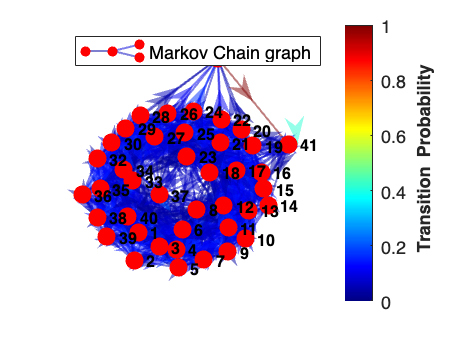

mc = dtmc(P);   % building the Markov Chain
figure(1)
graphplot(mc,'ColorEdges',true);    % plotting the graph
legend('Markov Chain graph')

Obviously, since the graph is made of 41 nodes, its plot is very chaotic and difficult to interpret.

Luckily, there are a few cool tools we can use. From theory, we know that if a Markov chain is positive recurrent, then we can extract the so-called **stationary distribution** from the transition matrix: it is a vector that indicates the expected long-term fraction of time that the process spends in each state. This is the case here, as every state will be visited with a probability of 1 if we play the game for an infinite amount of time. Let's compute the stationary distribution then!

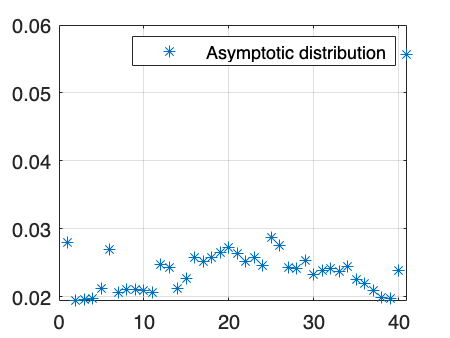

sd = asymptotics(mc);
figure(2)
plot(1:N+1, sd, '*')
grid on
legend('Asymptotic distribution')

From this plot we can easily see that, apart from *Jail*, the spaces that will be visited most frequently are the 1st (GO!), the 25th (Trafalgar Square) and those that can be directly reached from *Jail*. Now, let me comment on this result:

- The asymptotic probability of reaching Jail is much higher than the other probabilities. This is a consequence of the approximations that I made, as players can be stuck in Jail for many turns;

- The 1st and the 25th spaces have two of the highest probabilities because of the Chance and Community Chest cards "Advance to Go" and "Go to Trafalgar Square". This can also be observed with the other spaces that share this characteristic.

This means that, if you play by my rules, you might want to seriously consider purchasing these spaces. Of course, I could expand my study to analyze the best spaces to purchase from an economic perspective, but I’ll leave that for another time, as it isn’t the main objective of this project.

After these considerations regarding the overall probabilistic structure of the game, I have one more additional remark I’d like to share. First of all, while playing, it would be useful to have an idea of where a player might expect to land in the upcoming turns. This is why I built the following function (the code can be found in the repository):

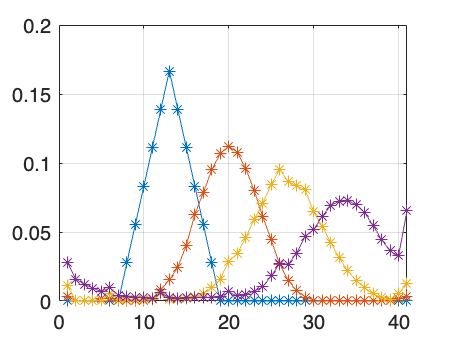

position = 6;
n = 4;
next_n_turns(position, P, n)

As you can see, this function displays the plot of the probabilities of being on a specific space after 1,..., n steps starting from a given position.

## Conclusion

I hope that you found this project interesting and (maybe) useful. I realize that discrete-time Markov Chains may not be the ideal stochastic tool for modeling the random movement of tokens in Monopoly, but for now, this is the closest model to that purpose among those I’ve studied. Once again, any suggestions for improving the project are very welcome. Additionally, if you know of any models that might better describe this phenomenon, please let me know.